# Module 3

## Exercise 3.6

G = tf(1,[1 0])*tf(1,[1 1])

G =
 
     1
  -------
  s^2 + s
 
Continuous-time transfer function.



Z = []; %the zeros
P = [-1,0]; %poles
K = 1; %gain
Ga = zpk(Z,P,K)

Ga =
 
     1
  -------
  s (s+1)
 
Continuous-time zero/pole/gain model.



Z = []; %the zeros
P = [1,2]; %poles
K = 1; %gain
Gb = zpk(Z,P,K)

Gb =
 
       1
  -----------
  (s-1) (s-2)
 
Continuous-time zero/pole/gain model.



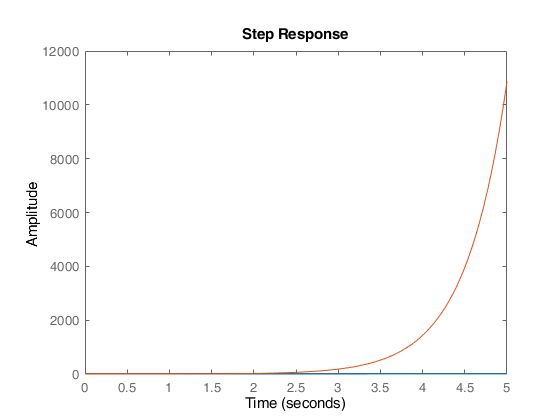

figure()
clf;
hold on
step(Ga,5)
step(Gb,5)

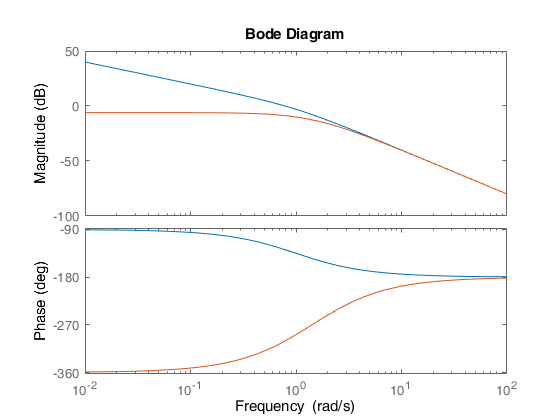

figure()
clf;
hold on
bode(Ga)
bode(Gb)

## Exercise 3.8

f = 1:1:1000

f =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


Z = []; %the zeros
P = [-20,-5]; %poles
K = 5; %gain
G1 = zpk(Z,P,K)

G1 =
 
       5
  ------------
  (s+20) (s+5)
 
Continuous-time zero/pole/gain model.



num = [5];
den = [1 1 100];
G2 = tf(num,den)

G2 =
 
        5
  -------------
  s^2 + s + 100
 
Continuous-time transfer function.



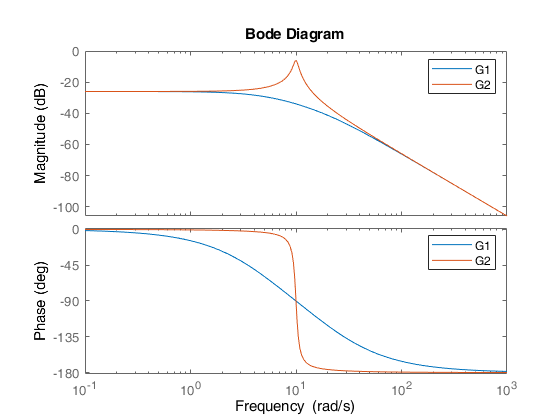

figure()
clf;
hold on
bode(G1)
bode(G2)
axh = findall(gcf, 'type', 'axes'); %setting the legend of both plots   
legend(axh(2),{'G1','G2'})
legend(axh(3),{'G1','G2'})

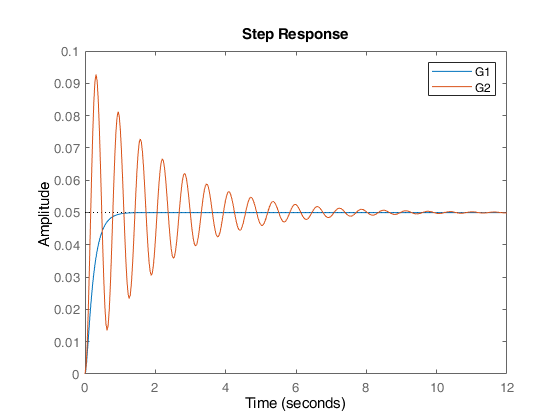


figure()
clf;
hold on
step(G1)
step(G2)
legend('G1','G2')